Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 7a -- DFT of Data

%{
    This will be a script that will solve the problems in assigment 7a for
    Digital Signal Processing.

    Sam Kramer
    Feb 28th, 2023
%}

% --Script setup
    clear; clc; close all; format compact;

### Problem Description:

Now that you have successfully completed assignment 7, here is a simple extension of that effort. Use the vectors you generated in assignment 7, ( Create a data vector of a 50 Hz(cosine, amplitude 1.2) that is periodic in the data vector. Use a sample rate of 1000 samples/sec for 0.5 sec.)

- Use the FFT function in Matlab to generate the spectrum. Plot this spectrum, magnitude, phase properly scaled and labeled Plot only up to the Nyquist frequency.

- If you remember, assignment 1 was to watch a video extolling the historical significance of the FFT. Return to that video and identify the error that is made in discussing the calculation of the DFT

### Using MATLAB FFT() Function:

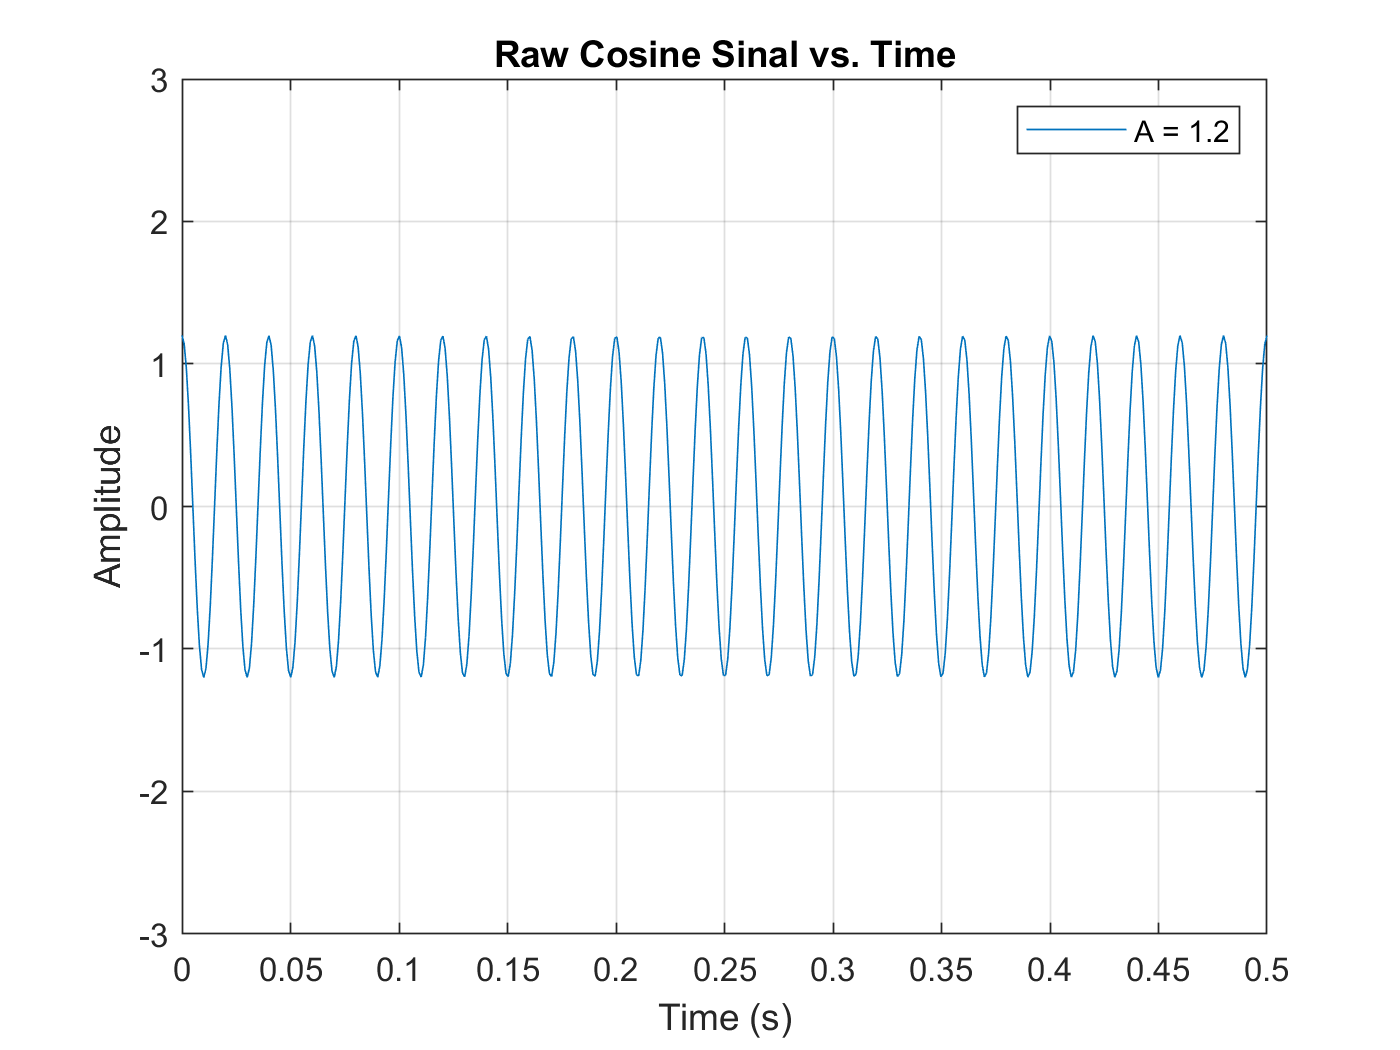

% --Parameters
    T = 0.5;                                    % Period;
    N = 1000*T;                                 % Sample frequency (fs/2)
    time = linspace(0,T,N);                     % Time vector
    amplitude = 1.2;                            % Cosine amplitude
    frequency = 50;                             % frequency of cosine (Hz)
    nyq = N/2;                                  % Nyquist cutoff point
    
% --Calculate Cosine wave
    frequency = frequency * 2 * pi;             % frequency (rad/s)
    wave = amplitude* cos(frequency .* time);   % Cosine wave
    
    % --Plot wave
        figure (1)
        plot(time,wave)
            ylim([-3 3])
            xlabel('Time (s)')
            ylabel('Amplitude')
            title('Raw Cosine Sinal vs. Time')
            legend('A = 1.2')
            grid on

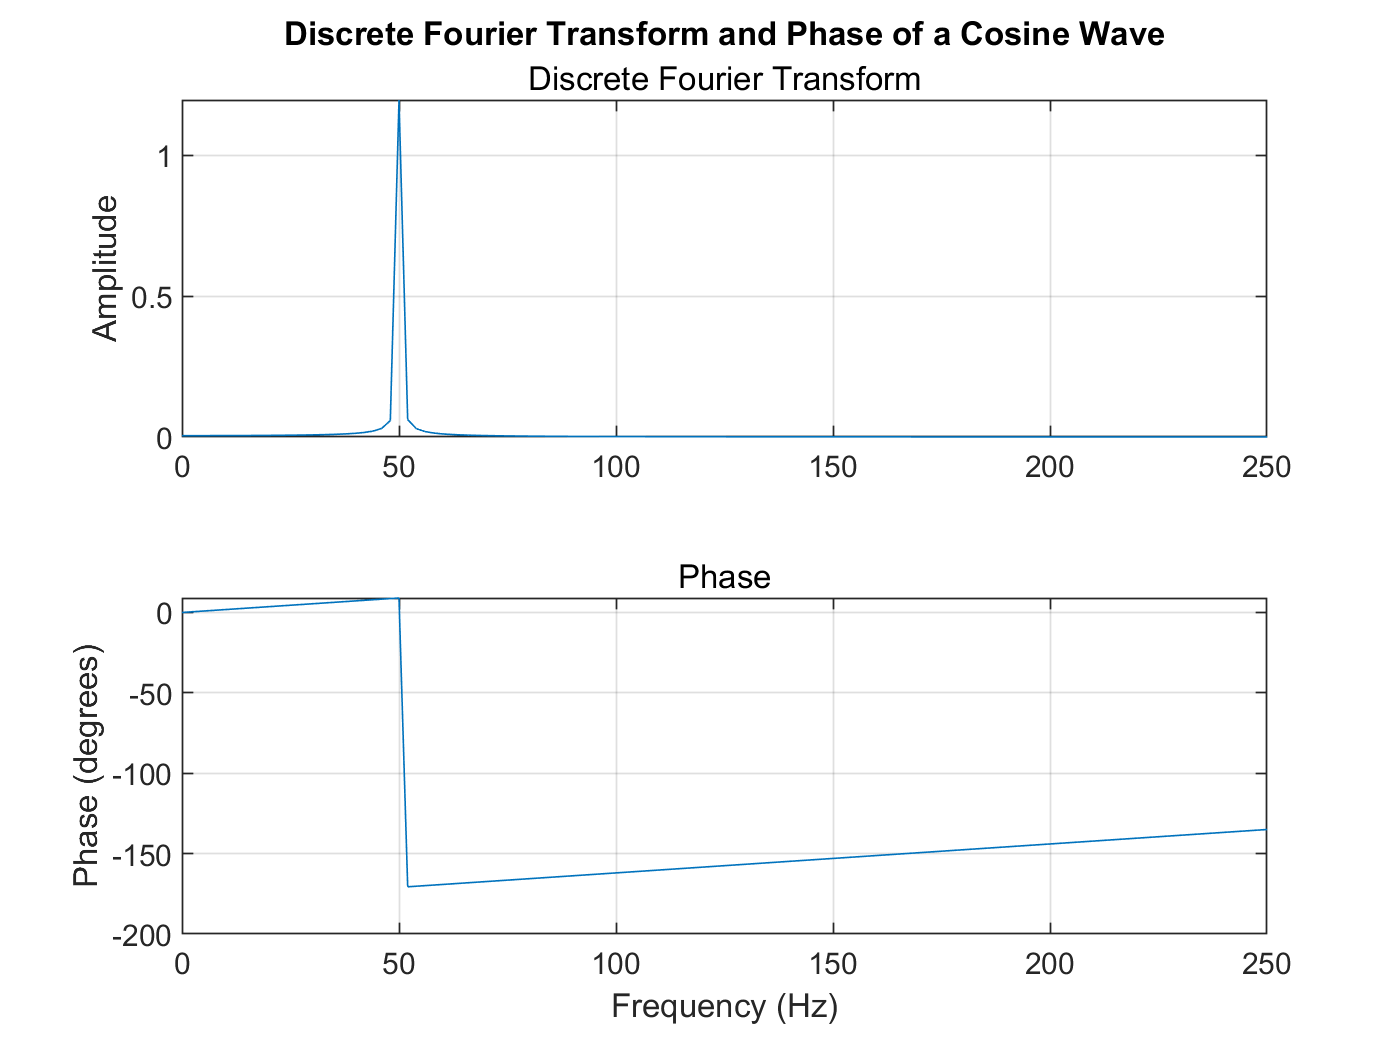

            hold on
            
% --FFT of cosine wave
    values = fft(wave);
    magnitude = abs(values);
    amplitude = (2/N).*magnitude;
    amplitude = amplitude(1:N/2);
    freq = 0:(1/T):(N - 1/T);
    
% --Calculating phase
    phase = atan2d(imag(values),real(values));
    phase = phase(1:N/2);
    
% --Plot FFT of data
    figure(2)
    subplot(2,1,1)
    plot(freq,amplitude)
        xlim([0 nyq])
        title('Discrete Fourier Transform and Phase of a Cosine Wave')
        subtitle('Discrete Fourier Transform')
        ylabel('Amplitude')
        grid on
        hold on
        
    subplot(2,1,2)
    plot(freq, phase)
        xlim([0 nyq])
        subtitle('Phase')
        ylabel('Phase (degrees)')
        xlabel('Frequency (Hz)')
        grid on

        hold on

### Mistakes in the Video:

    In assignment 1 we watched a youtube video by Veritasium on the FFT algorithm. However, there were some issues with the video. The first of those being the frequency bins that he mentions. When he starts to discuss the frequency resolution as a function of the period, he mentions that the frequency resolution is a function of the period and says that "The shorter the duration of the signal, the harder it is to tell frequencies apart" and then states that the frequencies calculated makes frequency bins like a histogram function. This is not the case, the actuality is that we still measure the frequency at a discrete frequency, however the space between the frequencies cannot be assumed like how they are in the video. The bins don't get wider, it is the frequencies at which we can calculate the amplitude get more spread out. 